%% Example 7.3: Butterworth via bilinear transform (Td = 1)
clear; clc;

%-------------------------------
% 1) Specs (Eqs. 7.28a–b)
%-------------------------------
Ap_amp = 0.89125;         % passband lower bound |H| >= 0.89125
As_amp = 0.17783;         % stopband upper bound |H| <= 0.17783
wp      = 0.2*pi;         % passband edge (digital rad)
ws      = 0.3*pi;         % stopband edge (digital rad)
Td      = 1;              % sampling period (book uses Td = 1)

% Convert amplitude specs to dB for buttord cross-check
Rp = -20*log10(Ap_amp);   % ≈ 0.99 dB
Rs = -20*log10(As_amp);   % = 15 dB

%---------------------------------------
% 2) Prewarp the edges (Eq. 7.26 → 7.29)
%---------------------------------------
Wp = (2/Td)*tan(wp/2);    % = 2*tan(0.1*pi)
Ws = (2/Td)*tan(ws/2);    % = 2*tan(0.15*pi)

%---------------------------------------
% 3) Order from Eq. (7.33); cutoff from (7.32b)
%---------------------------------------
N_real = log( ((1/As_amp)^2 - 1) / ((1/Ap_amp)^2 - 1) ) ...
         / ( 2*log(Ws/Wp) );                 % Eq. (7.33) using natural logs
N = ceil(N_real);                             % Butterworth order must be integer

% Choose Omega_c to meet stopband exactly (book does this): Eq. (7.32b)
Oc = Ws / (((1/As_amp)^2 - 1)^(1/(2*N)));    % analog 3 dB cutoff

fprintf('Eq. (7.33): N* = %.6f  → choose N = %d\n', N_real, N);

Eq. (7.33): N* = 5.304408  → choose N = 6


fprintf('From (7.32b): Omega_c = %.6f rad/s\n\n', Oc);

From (7.32b): Omega_c = 0.766231 rad/s




%---------------------------------------
% 4) Continuous-time Butterworth Hc(s)
%---------------------------------------
% Build Butterworth filter manually (without DSP Toolbox)
% For the factored (biquad) form in (7.34), compute the second-order sections.
% Butterworth LHP pole angles for N=6 give:
k  = 1:(N/2);
a1 = 2*Oc*sin((2*k-1)*pi/(2*N));               % 2*ζ_k*Oc (three values)
a0 = Oc^2 * ones(size(k));                     % Oc^2 (same in all three biquads)

% Numerator constant equals Oc^N (so that Hc(0)=1)
Kc = Oc^N;

% Build full denominator polynomial from biquads
% Each biquad is (s^2 + a1*s + a0)
as = [1];  % start with 1
for i = 1:numel(k)
    % Multiply current denominator by (s^2 + a1(i)*s + a0(i))
    biquad = [1, a1(i), a0(i)];
    as = conv(as, biquad);
end

% If N is odd, add first-order section (s + Oc)
if mod(N, 2) == 1
    as = conv(as, [1, Oc]);
end

% Numerator for analog filter: just the constant Kc
bs = Kc;

fprintf('Hc(s) in the (7.34) factored form:\n');

Hc(s) in the (7.34) factored form:


for i = 1:numel(k)
    fprintf('  (s^2 + %.4f s + %.4f)\n', a1(i), a0(i));
end

  (s^2 + 0.3966 s + 0.5871)
  (s^2 + 1.0836 s + 0.5871)
  (s^2 + 1.4802 s + 0.5871)


fprintf('Numerator constant Kc = Oc^N = %.5f\n\n', Kc);

Numerator constant Kc = Oc^N = 0.20238




%---------------------------------------
% 5) Bilinear transform to get H(z) (Td=1)
%---------------------------------------
% Manual bilinear transform: s = 2/Td * (1 - z^-1)/(1 + z^-1)
% For Td=1: s = 2*(1 - z^-1)/(1 + z^-1)
Td = 1;
[bz, az] = manual_bilinear(bs, as, Td);        % digital IIR, bilinear with Td=1

% Factor to three second-order denominators (to match 7.35)
% Using the closed-form mapping for each analog biquad:
A = zeros(numel(k), 3);
for i = 1:numel(k)
    den_i = 4 + 2*a1(i) + a0(i);                      % normalizing constant
    A(i,:) = [1, (-8 + 2*a0(i))/den_i, (4 - 2*a1(i) + a0(i))/den_i];
end

% The bilinear transform forces N zeros at z=-1 ⇒ numerator is g*(1+z^-1)^N.
% Its scalar g comes from the analog constant and the per-section normalizers:
g = Kc / prod(4 + 2*a1 + a0);
p = 1;  % build (1 + z^-1)^N
bin = 1;
for i = 1:N
    bin = conv(bin, [1 1]);
end
b_factored = g * bin;   % expected numerator

% Print (7.35)-style result
fprintf('H(z) (Eq. 7.35 form):\n');

H(z) (Eq. 7.35 form):


fprintf('  Numerator: %.7f * (1 + z^{-1})^%d\n', g, N);

  Numerator: 0.0007378 * (1 + z^{-1})^6


for i = 1:size(A,1)
    fprintf('  Denominator section %d: 1 %+.4f z^{-1} %+0.4f z^{-2}\n', ...
        i, A(i,2), A(i,3));
end

  Denominator section 1: 1 -1.2686 z^{-1} +0.7051 z^{-2}
  Denominator section 2: 1 -1.0106 z^{-1} +0.3583 z^{-2}
  Denominator section 3: 1 -0.9044 z^{-1} +0.2155 z^{-2}


fprintf('\nCheck (numerator): max|b_bilinear - g*(1+z^{-1})^N| = %.3e\n\n', ...
        norm(bz - b_factored, inf));


Check (numerator): max|b_bilinear - g*(1+z^{-1})^N| = 1.333e-02




%---------------------------------------
% 6) Frequency response & Fig. 7.11-style plots
%---------------------------------------
nfft = 4096;
% Manual frequency response calculation
w = linspace(0, pi, nfft)';
z = exp(1j*w);  % z = e^(jω)
H = manual_freqz(bz, az, z);
mag = abs(H);
magdB = 20*log10(mag);

% Group delay: -d(angle(H))/dω
wgd = w;
gd = manual_grpdelay(bz, az, z, w);

% Evaluate at the two edges for verification
wcheck = [0.2*pi 0.3*pi];
zcheck = exp(1j*wcheck);
Hcpts = manual_freqz(bz, az, zcheck);
fprintf('At w = 0.2pi:  %6.3f dB\n', 20*log10(abs(Hcpts(1))));

At w = 0.2pi:  -13.878 dB


fprintf('At w = 0.3pi:  %6.3f dB\n', 20*log10(abs(Hcpts(2))));

At w = 0.3pi:  -14.094 dB


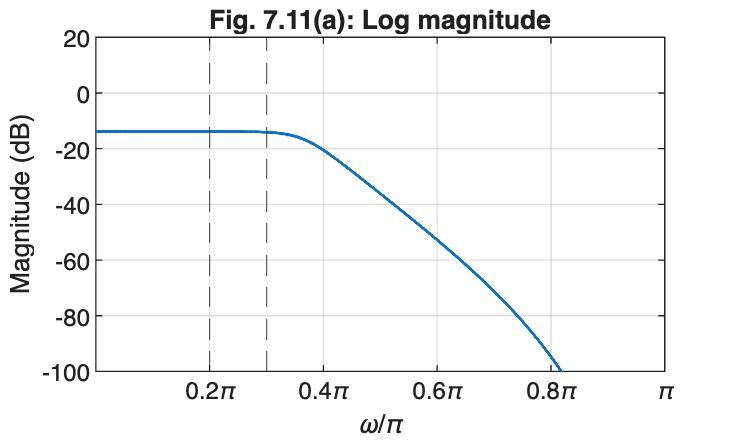


% Plot (a) log magnitude, (b) magnitude, (c) group delay
% Create 3 separate figures and save each to a file

% Figure 1: Log magnitude
figure('Name','Log magnitude','Color','w');
plot(w/pi, magdB, 'LineWidth', 1.2); grid on;
xline(0.2,'--'); xline(0.3,'--');
ylabel('Magnitude (dB)'); xlabel('\omega/\pi'); 
xlim([0 1]); ylim([-100 20]);
xticks([0.2 0.4 0.6 0.8 1.0]);
xticklabels({'0.2\pi', '0.4\pi', '0.6\pi', '0.8\pi', '\pi'});
title('Fig. 7.11(a): Log magnitude');
saveas(gcf, 'log_magnitude.png');

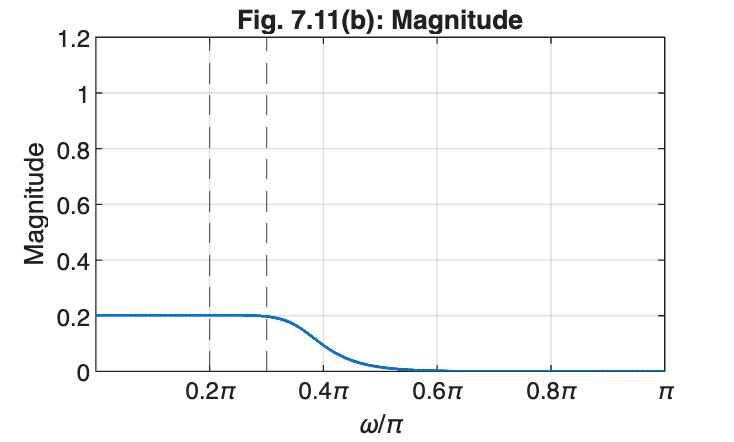


% Figure 2: Magnitude
figure('Name','Magnitude','Color','w');
plot(w/pi, mag, 'LineWidth', 1.2); grid on;
xline(0.2,'--'); xline(0.3,'--');
ylabel('Magnitude'); xlabel('\omega/\pi'); 
xlim([0 1]); ylim([0 1.2]);
xticks([0.2 0.4 0.6 0.8 1.0]);
xticklabels({'0.2\pi', '0.4\pi', '0.6\pi', '0.8\pi', '\pi'});
title('Fig. 7.11(b): Magnitude');
saveas(gcf, 'magnitude.png');

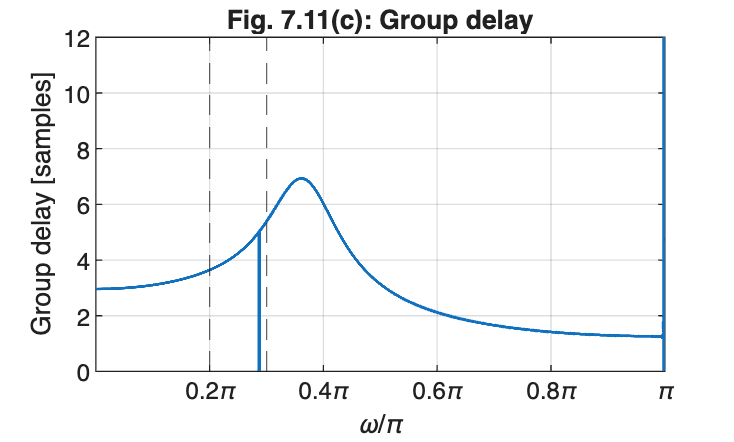


% Figure 3: Group delay
figure('Name','Group delay','Color','w');
plot(wgd/pi, gd, 'LineWidth', 1.2); grid on;
xline(0.2,'--'); xline(0.3,'--');
xlabel('\omega/\pi'); ylabel('Group delay [samples]'); 
xlim([0 1]); ylim([0 12]);
xticks([0.2 0.4 0.6 0.8 1.0]);
xticklabels({'0.2\pi', '0.4\pi', '0.6\pi', '0.8\pi', '\pi'});
title('Fig. 7.11(c): Group delay');
saveas(gcf, 'group_delay.png');


%---------------------------------------
% 7) (Optional) Cross-check with buttord
%---------------------------------------
% buttord check skipped (requires DSP Toolbox)
% Already computed N from Eq. (7.33) above
fprintf('\nFilter order check: N = %d (computed from Eq. 7.33)\n', N);


Filter order check: N = 6 (computed from Eq. 7.33)



%---------------------------------------
% Helper functions (manual implementations without DSP Toolbox)
%---------------------------------------
function [bz, az] = manual_bilinear(bs, as, Td)
    % Manual bilinear transform: s = (2/Td) * (1 - z^-1)/(1 + z^-1)
    % This converts analog filter (bs, as) to digital filter (bz, az)
    
    % Normalize to ensure as(1) = 1
    if as(1) ~= 1
        bs = bs / as(1);
        as = as / as(1);
    end
    
    M = length(bs);
    N = length(as);
    
    % Transformation constant
    T = 2/Td;
    
    % Convert to z-domain using substitution
    % H(z) = Hc(s)|_{s = T*(1-z^-1)/(1+z^-1)}
    % Standard method: multiply numerator and denominator by (1+z^-1)^(N-1)
    
    % Build (1+z^-1)^(N-1) polynomial
    one_plus_z = [1, 1];  % (1 + z^-1)
    one_plus_z_power = 1;
    for i = 1:(N-1)
        one_plus_z_power = conv(one_plus_z_power, one_plus_z);
    end
    
    % Transform numerator: each term bs(k)*s^(k-1) becomes
    % bs(k) * T^(k-1) * (1-z^-1)^(k-1) * (1+z^-1)^(N-1-(k-1))
    bz_temp = zeros(1, length(one_plus_z_power));
    for k = 1:M
        if bs(k) ~= 0
            power_s = k - 1;  % power of s
            % Build (1-z^-1)^power_s
            one_minus_z = [1, -1];  % (1 - z^-1)
            one_minus_z_power = 1;
            for i = 1:power_s
                one_minus_z_power = conv(one_minus_z_power, one_minus_z);
            end
            
            % Build (1+z^-1)^(N-1-power_s)
            one_plus_z_power2 = 1;
            if (N-1-power_s) > 0
                for i = 1:(N-1-power_s)
                    one_plus_z_power2 = conv(one_plus_z_power2, one_plus_z);
                end
            end
            
            % Combine: T^power_s * (1-z^-1)^power_s * (1+z^-1)^(N-1-power_s)
            term = bs(k) * (T^power_s) * conv(one_minus_z_power, one_plus_z_power2);
            
            % Pad to match length
            if length(term) < length(bz_temp)
                term = [term, zeros(1, length(bz_temp) - length(term))];
            elseif length(term) > length(bz_temp)
                bz_temp = [bz_temp, zeros(1, length(term) - length(bz_temp))];
            end
            bz_temp = bz_temp + term;
        end
    end
    
    % Transform denominator: each term as(k)*s^(k-1) becomes
    % as(k) * T^(k-1) * (1-z^-1)^(k-1) * (1+z^-1)^(N-1-(k-1))
    az_temp = zeros(1, length(one_plus_z_power));
    for k = 1:N
        if as(k) ~= 0
            power_s = k - 1;  % power of s
            % Build (1-z^-1)^power_s
            one_minus_z = [1, -1];  % (1 - z^-1)
            one_minus_z_power = 1;
            for i = 1:power_s
                one_minus_z_power = conv(one_minus_z_power, one_minus_z);
            end
            
            % Build (1+z^-1)^(N-1-power_s)
            one_plus_z_power2 = 1;
            if (N-1-power_s) > 0
                for i = 1:(N-1-power_s)
                    one_plus_z_power2 = conv(one_plus_z_power2, one_plus_z);
                end
            end
            
            % Combine: T^power_s * (1-z^-1)^power_s * (1+z^-1)^(N-1-power_s)
            term = as(k) * (T^power_s) * conv(one_minus_z_power, one_plus_z_power2);
            
            % Pad to match length
            if length(term) < length(az_temp)
                term = [term, zeros(1, length(az_temp) - length(term))];
            elseif length(term) > length(az_temp)
                az_temp = [az_temp, zeros(1, length(term) - length(az_temp))];
            end
            az_temp = az_temp + term;
        end
    end
    
    % Normalize so az(1) = 1
    bz = bz_temp / az_temp(1);
    az = az_temp / az_temp(1);
end

function H = manual_freqz(bz, az, z)
    % Manual frequency response: H(z) = B(z)/A(z) evaluated at z values
    % bz, az are polynomial coefficients in z^-1 (standard MATLAB format)
    % z can be scalar, vector, or array
    
    % Evaluate numerator B(z) = sum(bz(k) * z^-(k-1))
    B = zeros(size(z));
    for k = 1:length(bz)
        if bz(k) ~= 0
            B = B + bz(k) * (z.^-(k-1));
        end
    end
    
    % Evaluate denominator A(z) = sum(az(k) * z^-(k-1))
    A = zeros(size(z));
    for k = 1:length(az)
        if az(k) ~= 0
            A = A + az(k) * (z.^-(k-1));
        end
    end
    
    H = B ./ A;
end

function gd = manual_grpdelay(bz, az, z, w)
    % Manual group delay calculation: -d(angle(H))/dω
    % Using numerical derivative of phase
    
    H = manual_freqz(bz, az, z);
    phase = angle(H);
    
    % Compute derivative using central differences for interior points
    % Use forward difference at start, backward difference at end
    gd = zeros(size(w));
    if length(w) > 1
        % Interior points: central difference
        gd(2:end-1) = -(phase(3:end) - phase(1:end-2)) ./ (w(3:end) - w(1:end-2));
        % First point: forward difference
        gd(1) = -(phase(2) - phase(1)) / (w(2) - w(1));
        % Last point: backward difference
        gd(end) = -(phase(end) - phase(end-1)) / (w(end) - w(end-1));
    end
end


